% Parameters
fs_noise = 20000;         % Sampling frequency
N_sinc = 20;              % Sinc reconstruction window size
sigma = 0.1;              % Noise standard deviation
t_rec = 0:1/fs_noise:max(t);  % Match the domain to avoid matrix blow-up

% Sample Signals
[t_samp, x_orig_samp] = sample_signal(t, x, fs_noise);
[~, x_low_samp]       = sample_signal(t, x_low_filtered, fs_noise);
[~, x_band_samp]      = sample_signal(t, x_band_filtered, fs_noise);

% Add Gaussian Noise
rng(340);
x_orig_noisy  = x_orig_samp  + sigma * randn(size(x_orig_samp));
x_low_noisy   = x_low_samp   + sigma * randn(size(x_low_samp));
x_band_noisy  = x_band_samp  + sigma * randn(size(x_band_samp));

% Reconstruct Noisy Signals
xr_orig_noise = reconstruct(t_rec, x_orig_noisy, fs_noise, N_sinc);
xr_low_noise  = reconstruct(t_rec, x_low_noisy,  fs_noise, N_sinc);
xr_band_noise = reconstruct(t_rec, x_band_noisy, fs_noise, N_sinc);

% Interpolate original signals onto t_rec for fair MSE
x_interp      = interp1(t, x, t_rec, 'linear');
x_low_interp  = interp1(t, x_low_filtered, t_rec, 'linear');
x_band_interp = interp1(t, x_band_filtered, t_rec, 'linear');

% MSE Calculation
mse_orig  = mean((x_interp - xr_orig_noise).^2);
mse_low   = mean((x_low_interp - xr_low_noise).^2);
mse_band  = mean((x_band_interp - xr_band_noise).^2);

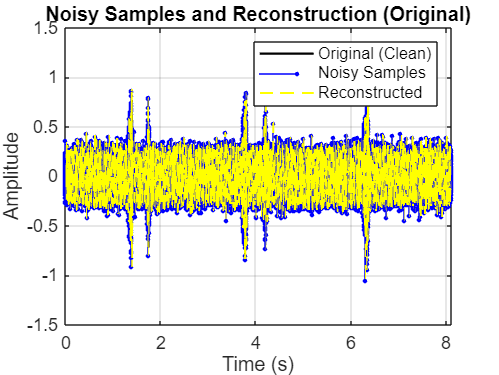

% ORIGINAL SIGNAL PLOT
t_sample = 0:1/fs_noise:max(t);
figure('Name', 'Original Signal Reconstruction with Noise', 'NumberTitle', 'off');
plot(t_rec, x_interp, 'k', 'LineWidth', 1.2); hold on;
stem(t_sample, x_orig_noisy, 'bo', 'filled', 'MarkerSize', 2);  % Noisy samples
plot(t_rec, xr_orig_noise, 'y--', 'LineWidth', 1.2);
title('Noisy Samples and Reconstruction (Original)');
xlabel('Time (s)'); ylabel('Amplitude');
legend('Original (Clean)', 'Noisy Samples', 'Reconstructed'); grid on;
xlim([0, max(t_rec)]);

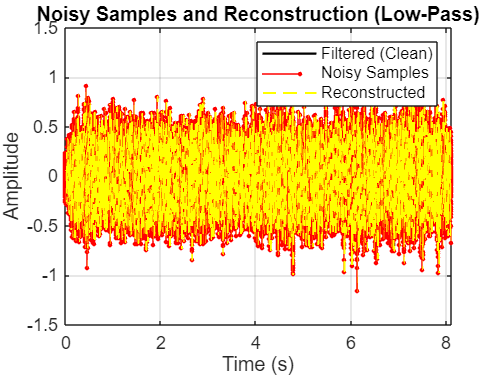

% LOW-PASS SIGNAL PLOT
figure('Name', 'Low-Pass Filtered Signal Reconstruction with Noise', 'NumberTitle', 'off');
plot(t_rec, x_low_interp, 'k', 'LineWidth', 1.2); hold on;
stem(t_sample, x_low_noisy, 'ro', 'filled', 'MarkerSize', 2);  % Noisy samples
plot(t_rec, xr_low_noise, 'y--', 'LineWidth', 1.2);
title('Noisy Samples and Reconstruction (Low-Pass)');
xlabel('Time (s)'); ylabel('Amplitude');
legend('Filtered (Clean)', 'Noisy Samples', 'Reconstructed'); grid on;
xlim([0, max(t_rec)]);

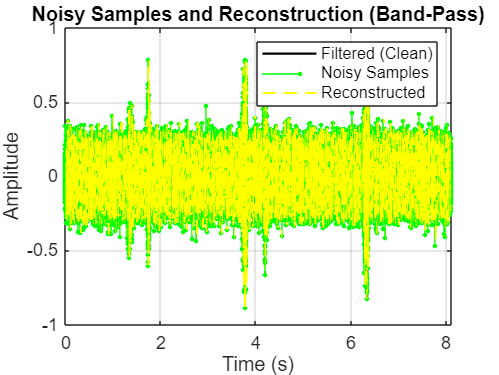

% BAND-PASS SIGNAL PLOT
figure('Name', 'Band-Pass Filtered Signal Reconstruction with Noise', 'NumberTitle', 'off');
plot(t_rec, x_band_interp, 'k', 'LineWidth', 1.2); hold on;
stem(t_sample, x_band_noisy, 'go', 'filled', 'MarkerSize', 2);  % Noisy samples
plot(t_rec, xr_band_noise, 'y--', 'LineWidth', 1.2);
title('Noisy Samples and Reconstruction (Band-Pass)');
xlabel('Time (s)'); ylabel('Amplitude');
legend('Filtered (Clean)', 'Noisy Samples', 'Reconstructed'); grid on;
xlim([0, max(t_rec)]);

% Print MSE values to console for LaTeX use
fprintf('MSE (Original): %.4e\n', mse_orig);

MSE (Original): 1.0084e-02


fprintf('MSE (Low-Pass): %.4e\n', mse_low);

MSE (Low-Pass): 1.0015e-02


fprintf('MSE (Band-Pass): %.4e\n', mse_band);

MSE (Band-Pass): 1.0065e-02


% Normalize signals to prevent clipping
xr_orig_audio  = xr_orig_noise / max(abs(xr_orig_noise));
xr_low_audio   = xr_low_noise  / max(abs(xr_low_noise));
xr_band_audio  = xr_band_noise / max(abs(xr_band_noise));

% Write to WAV files
audiowrite('../../audios/reconstructed_original_noisy.wav',  xr_orig_audio,  fs_noise);
audiowrite('../../audios/reconstructed_lowpass_noisy.wav',   xr_low_audio,   fs_noise);
audiowrite('../../audios/reconstructed_bandpass_noisy.wav',  xr_band_audio,  fs_noise);

fprintf('Audio files saved for all reconstructed signals.\n');